% ejercicio1_markov.m
clear; close all; clc;

%% Parámetros y tiempo
r  = 0.05;    % radio de rueda [m]
L  = 0.3;     % separación ejes [m]
ts = 1;       % paso de muestreo [s]
N  = 12;      % número de pasos
t  = 0:ts:N;  % 0,1,...,12 (N+1 puntos)

%% Inicializa pose
x = zeros(1,N+1);
y = zeros(1,N+1);
phi = zeros(1,N+1);
x(1) = -1;    % posición inicial x
y(1) = -5;    % posición inicial y
phi(1) =  0;  % orientación inicial [rad]

%% Control discreto (v, ω) en cada paso
v = [1.0, 0.0, 1.0, 0.0, 1.0, 0.0, 1.0, 0.0, 1.0, 0.0, 1.0, 0.0];      % [m/s]
w = [0.0, pi/3, 0.0, pi/3, 0.0, pi/3, 0.0, pi/3, 0.0, pi/3, 0.0, pi/3];% [rad/s]

%% Integración Euler
for k = 1:N
    phi(k+1) = phi(k) + w(k)*ts;
    x(k+1)   = x(k) + v(k)*cos(phi(k))*ts;
    y(k+1)   = y(k) + v(k)*sin(phi(k))*ts;
end

%% Cálculo velocidades de rueda
omega_R = (2*v + w*L)/(2*r);
omega_L = (2*v - w*L)/(2*r);

%% Tabla de resultados
T1 = table( ...
  t', ...
  [v, 0]', ...                % desplazamos un cero final para alinear
  [w, 0]', ...
  [omega_R,0]', ...
  [omega_L,0]', ...
  x', ...
  y', ...
  rad2deg(phi') , ...
  'VariableNames', ...
  {'t_s','v_m_s','omega_rad_s','omega_R','omega_L','x_m','y_m','theta_deg'});
disp(T1);

    t_s    v_m_s    omega_rad_s    omega_R    omega_L       x_m          y_m      theta_deg
    ___    _____    ___________    _______    _______    __________    _______    _________

     0       1             0           20          20            -1         -5         0   
     1       0        1.0472       3.1416     -3.1416             0         -5         0   
     2       1             0           20          20             0         -5        60   
     3       0        1.0472       3.1416     -3.1416           0.5     -4.134        60   
     4       1             0           20          20           0.5     -4.134       120   
     5       0        1.0472       3.1416     -3.1416    3.3307e-16    -3.2679     

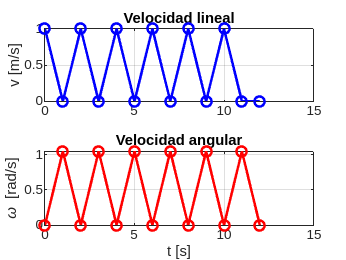


%% Gráfica v y ω
figure;
subplot(2,1,1)
plot(t, [v,0], 'b-o','LineWidth',1.5), grid on
ylabel('v [m/s]'), title('Velocidad lineal')
subplot(2,1,2)
plot(t, [w,0], 'r-o','LineWidth',1.5), grid on
xlabel('t [s]'), ylabel('\omega [rad/s]'), title('Velocidad angular')

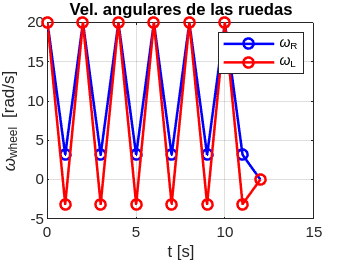


%% Gráfica de velocidades de rueda
figure;
plot(t, [omega_R,0], 'b-o', t, [omega_L,0], 'r-o','LineWidth',1.5), grid on
xlabel('t [s]'), ylabel('\omega_{wheel} [rad/s]')
legend('\omega_R','\omega_L'), title('Vel. angulares de las ruedas')

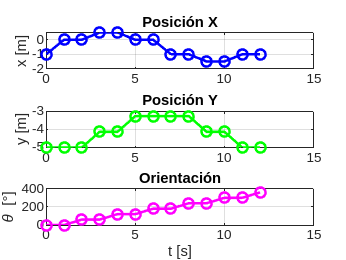


%% Gráficas de pose
figure;
subplot(3,1,1)
plot(t, x, 'b-o','LineWidth',1.5), grid on
ylabel('x [m]'), title('Posición X')
subplot(3,1,2)
plot(t, y, 'g-o','LineWidth',1.5), grid on
ylabel('y [m]'), title('Posición Y')
subplot(3,1,3)
plot(t, rad2deg(phi), 'm-o','LineWidth',1.5), grid on
xlabel('t [s]'), ylabel('\theta [°]'), title('Orientación')

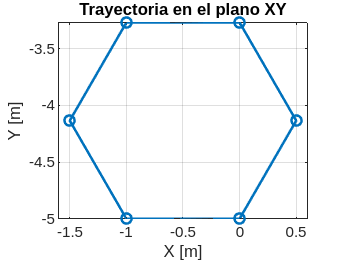


%% Trayectoria estática XY
figure;
plot(x, y, '-o','LineWidth',1.5), axis equal, grid on
xlabel('X [m]'), ylabel('Y [m]'), title('Trayectoria en el plano XY')

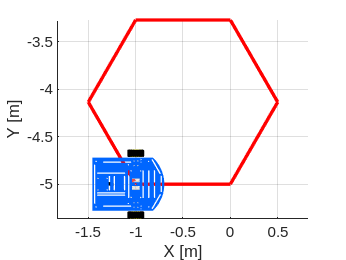


%% Animación 2D
figure; axis equal; grid on; hold on
xlabel('X [m]'), ylabel('Y [m]'), view(2)
MobileRobot_5; scale=4;
hR = MobilePlot_4(x(1), y(1), phi(1), scale);
hT = plot(x(1), y(1), 'r-','LineWidth',2);
for k=2:length(x)
    delete(hR); delete(hT)
    hR = MobilePlot_4(x(k), y(k), phi(k), scale);
    hT = plot(x(1:k), y(1:k), 'r-','LineWidth',2);
    pause(ts)
end